clear; % FIX IN REAL CODE = FIRC

# Tutorial 3 - Communications Link Budget Analysis

## Introduction

These tasks cover tutorial 3, which aims to deduce which of three given antennas with given properties is most well suited for the mission objective. The antenna needs to be operational at an altitude of 1336km with enough Link Margin to be able to communicate with the ground station and the ability to operate in the necessary frequency range of the ground station. Once these base requirements have been met, the antenna should, if possible, be optimised for minimum mass and noise temperature, and maximum beamwidth, so that it has the least influence on the spacecraft's dry mass, and therefore delta-v, and it can provide the clearest signal possible even if the antenna is not pointed perfectly towards the groundstation. This will mean that the attitude determination and control system will have to do much less work to constantly correct and perfectly point the spacecraft in the ideal direction to be able to receive and send data or instructions to or from the ground. 

### Task 1 - Identify Receiving and Transmitting Stations

The receiving element is the ground station and the transmitting element is the space segment because of the presence of 'Downlink Frequency', which indicates that data is being sent down from the space segment to the ground station. 

### Task 2 - Define Constants

For terms relating to the ground station, I have used 'gs' as a suffix, whereas if the term relates to the space segment, I have used 'ss'. 

For example, the Transmission Power of the ground station is given as P_Tgs, and the transmission power of an antenna in the space segment is given as P_Tss. 

#### Details of the communications link ground station:

P_Tgs = 35;                                 % [W] Transmission Power
T_Rgs = 257;                                % [K] Noise Temperature
D_gs = 4.5;                                 % [m] Antenna Diameter

#### Details of the communications link space segment:

For the space segment, I have created an array for each property, where the first index represents the values for the parabolic antenna, the second is for helix antenna, and the third index is for the horn antenna. This is useful as I will be using matrix multiplication later on, and it is a significantly shorter way of writing out all the constants. 

% antenna_property = [parabolic value, helix value, horn value];
P_Tss = [30, 90, 54];                       % [W] Transmission Power For Each Antenna
T_Rss = [156, 160, 170];                    % [K] Noise Temperature For Each Antenna
theta_bw = [35, 30, 33];                    % [deg] Antenna Beamwidth For Each Antenna
ss_mass = [30, 12, 2];                      % [kg] Mass For Each Antenna

#### Details of the platform communications link parameters:

BER = 8 * 10^(-6);                          % Bit Error Rate
R_b = 150;                                  % [Mbps] Transmission Rate
f_d = 8.9;                                  % [GHz] Downlink Frequency
L_i = 1.85;                                 % [dB] Implementation Losses
L_add = 7;                                  % [dB] Additional Losses
k = 1.38 * 10^(-23);                        % [JK^-1] Boltzmann Constant

### Task 3 - Identify and Rearrange Correct Gain Equations For Each Antenna

Each antenna has different equations for their respective gains, so it will be necessary to collect and rearrange each equation to find these values. 

#### Gain for the Parabolic Antenna

The empirical formula for gain for a parabolic antenna is given as:

Equation (8.20)

#### $G=17\ldotp 8+20\log \left(D\right)+20\log \left(f\right)$,

which is not useful yet since we do not know the frequency *f* or the antenna diameter *D*, however, we can combine the log terms to yield $20\log \left(f*D\right)$, and rearrange the following formula to make *f*D* the subject since we have *θ*:

Equation (8.19)

$\theta =\frac{21}{\left(f\right)\left(D\right)}$,

where $\theta$ is the antenna beamwidth, *f* is frequency, and *D* is the parabolic antenna's diameter. 


$$\left(f*D\right)=\frac{21}{\theta }$$


Therefore, the gain equation for a parabolic antenna turns into: 


$$G=17\ldotp 8+20\log \left(\frac{21}{\theta }\right)$$


#### Gain for the Helix Antenna

A similar approach is required for finding the gain of the Helix antenna with the information we are given. The main formula for gain for a helix antenna is: 

Equation (8.18)

#### $G=10\ldotp 3+10\log \left(\frac{\pi^2 D^2 L}{\lambda^3 }\right)$,

and the equation that we can rearrange is: 

Equation (8.17)

$\theta =\frac{52}{\sqrt{\frac{\pi^2 D^2 L}{\lambda^3 }}}$,

which, once rearranged, gives: 


$$\frac{\pi^2 D^2 L}{\lambda^3 }=\frac{{52}^2 }{\theta^2 }$$


Substituting the above equation into the intial gain equation: 


$$G=10\ldotp 3+20\log \left(\frac{52}{\theta }\right)$$


#### Gain for the Horn Antenna

Once again, the method for finding the gain of a horn antenna is similar to the previous two, where the initial gain formula is given as: 

Equation (8.16)

#### $G=20\log \left(\frac{\pi D}{\lambda }\right)-2\ldotp 8$,

and the *θ* formula to rearrange is:

Equation (8.15)

$\theta =\frac{255\lambda }{\pi D}\longrightarrow \frac{\pi D}{\lambda }=\frac{255}{\theta }$,

and the final equation for gain is:


$$G=20\log \left(\frac{255}{\theta }\right)-2\ldotp 8$$


### Task 4 - Calculate Gain For Each Antenna

Now that the individual antenna gain equations have been found, they must be calculated and stored into an array, which I have named 'antenna_gain'. For clarity, I have also made variables for each position in the array that are the gains for their respective antennas. 

#### Gain calculation for each antenna:

To calculate the gain of the antenna's we simply substitute in the known values for θ for each antenna. 

#### Parabolic antenna

Below is the equation for gain for the parabolic antenna, substituting in the value of θ = 35 [deg], which is given at the start of the tutorial as a constant. 


$$G=17\ldotp 8+20\log \left(\frac{21}{35}\right)=17\ldotp 8+-4\ldotp 437=13\ldotp 363\;\mathrm{dB}$$


G_para = 17 + 20*log10(21/theta_bw(1)); % [dB] Parabolic Antenna Gain

#### Helix antenna

The helix antenna's antenna beamwidth θ = 30 [deg], and the equation is shown below. 


$$G=10\ldotp 3+20\log \left(\frac{52}{30}\right)=10\ldotp 3+4\ldotp 778=15\ldotp 078\;\mathrm{dB}$$


G_heli = 10.3 + 20*log10(52/theta_bw(2)); % [dB] Helix Antenna Gain

#### Horn antenna

The horn antenna's antenna beamwidth θ = 33 [deg], and the equation is shown below. 


$$G=20\log \left(\frac{255}{33}\right)-2\ldotp 8=17\ldotp 761-2\ldotp 8=14\ldotp 961\;\mathrm{dB}$$


G_horn = 20*log10(255/theta_bw(3))-2.8; % [dB] Horn Antenna Gain

Now that the antenna's individual gains have been calculated, they must be established in an array. 

antenna_gain = [G_para, G_heli, G_horn]; % [dB, dB, dB] Antenna Gains

### Task 5 - Calculate Effective Isotropic Radiator Power For Each Antenna

Once the antenna gain array has been established, we can calculate the Effective Isotropic Radiator Power (EIRP) of each antenna and establish those values in an array as well. 

The EIRP depends on gain $G_T$, and power $P_T$, and the equation is shown below:

Equation (8.10)

#### 
$$G_T *P_T =\mathrm{EIRP}$$


Now, to calculate each EIRP using the antenna gain array and establish the EIRP array. Before this, however, the transmitted power *P_Tss* must be converted into decibel watts [dBW] to be able to add it to the antenna gain and receive *EIRP*.  

P_Tss_dBW = 10*log10(P_Tss); % [W]
EIRP = antenna_gain + P_Tss_dBW; % [dBW]

### Task 6 - Calculate Receiving Station Gain

To calculate the gain of the receiveing ground station, the correct equation to use is the same as the one used in the calculation of gain for the spacecraft's parabolic antenna because the receiving ground station is a parabolic antenna as well: 

Equation (8.20)


$$G=17\ldotp 8+20\log \left(D\right)+20\log \left(f\right)$$


However, in this case, since we have the antenna diameter and frequency, we can simply use the original equation instead of transforming it to find in terms of θ. Downlink frequency *f=8.9 [GHz]*, and antenna diameter *D = 4.5 [m]. *Additionally, there is no need to convert to Hz from GHz because the equation given required frequency in GHz already. 

$G=17\ldotp 8+20\log \left(4\ldotp 5\right)+20\log \left(8\ldotp 9\right)$;

G_gs = 17.8 + 20*log10(D_gs) + 20*log10(f_d); % [dB]

### Task 7 - Calculate Gain to Noise Density Ratio

To find the gain-to-noise density ratio, we have to first find the noise. 

Equation (8.22)

#### 
$$N_0 =10\log_{10} \left(k\right)+10\log_{10} \left(T_R \right)$$



$$N_0 =10\log_{10} \left(1\ldotp 38*{10}^{-23} \right)+10\log_{10} \left(257\right)$$



$$N_0 =-204\ldotp 5\;{\mathrm{dBWHz}}^{-1}$$


noise_gs = 10*log10(k) + 10*log10(T_Rgs); % [dBWHz^-1] Ground Station Noise

Now, we simply subtract the noise of the ground station from the calculated gain for the ground station to find the gain-to-noise density ratio as they are both already in decibel form:

Equation (8.25)

#### 
$$\mathrm{GRN0R}=10\log_{10} \left(\frac{G_{\mathrm{gs}} }{N_0 }\right)$$



$$\textrm{GRN0R}=G_{\textrm{gs}} -N_0$$



$$\textrm{GRN0R}=49\ldotp 85-\left(-204\ldotp 5\right)$$



$$\mathrm{GRN0R}=254\ldotp 35\;\mathrm{dBW}\;{\mathrm{Hz}}^{-1}$$


GRN0R = G_gs - noise_gs; % [dBWHz^-1] Gain-to-noise density ratio

### Task 8 - Create Altitude and Slant Range Arrays

Free space loss (FSL) calculation requires the declaration of an array of altitude ranges that start at the given minimum altitude of 250km and that go up to the maximum given altitude of 2500km. 

alt_range = linspace(250, 2500, 500); % [km] Altitude array from 250km to 2500km

This array is used to gather a range of link margins on a range of altitudes so that we can decide which antenna will be most effective. 

The next step is to calculate the slant range *S, *which is calculated for each altitude, and for this tutorial, we are considering the worst case scenario, where we assume the spacecraft is being viewed from a ground station at its furthest visible point, which is on the horizon. The equation for slant range is provided below, and for each calculation that uses a range, I will show the minimum and maximum values in the array in question: 

$S=\sqrt{{\left(R_e +h\right)}^2 -R_e^2 }$,

where R_e is the earth's radius and h is the orbital altitude


$$S_1 =\sqrt{{\left(6371+250\right)}^2 -{6371}^2 }=1\ldotp 80*{10}^3 \;m$$



$$S_{500} =\sqrt{{\left(6371+2500\right)}^2 -{6371}^2 }=6\ldotp 17*{10}^3 \;m$$


slant_range = sqrt((6371+alt_range).^2-6371^2); % FIRC replace with R_earth

We also have to calculate the wavelength of the transmitted signal, which is found by using the same equation that relates velocity, frequency, and wavelength for any wave of light. 


$$\lambda =\frac{v}{f}$$



$$\lambda =\frac{3*{10}^8 }{f_d }=\frac{3*{10}^8 }{8\ldotp 9*{10}^9 }$$



$$\lambda =0\ldotp 0337\;m$$


lambda = (3*10^8)/(f_d*10^9); % [m] Wavelength

### Task 9 - Calculate Free Space Loss

Calculating FSL using the previously calculated variables. 

FSL equation is given as: 

Equation (8.30)

#### 
$$L_{\mathrm{fs}} =10\log_{10} {\left(\frac{4\pi S}{\lambda }\right)}^2$$



$$L_{\textrm{fs}} =20\log_{10} \left(\frac{4\pi S}{\lambda }\right)$$


where λ is the wavelength of the signal, and S is the slant range. 


$$L_{\mathrm{fs1}} =20\log_{10} \left(\frac{4\pi *1800*{10}^3 }{0\ldotp 0337}\right)$$



$$L_{\textrm{fs1}} =176\ldotp 5\;\textrm{dB}$$



$$L_{\mathrm{fs500}} =20\log_{10} \left(\frac{4\pi *6170*{10}^3 }{0\ldotp 0337}\right)$$



$$L_{\mathrm{fs500}} =187\ldotp 2\;\mathrm{dB}$$


L_fs_dB = 20*log10(4*pi*slant_range.*10^3/lambda); % [dB] Free Space Loss

### Task 10 - Calculate Carrier to Noise Density Ratio

Now, to calculate Carrier to Noise Density Ratio (CN0R), the equation is once again simple addition as everything has already been worked out in decibel form: 

Equation (8.33)

#### 
$$\mathrm{CN0R}=\mathrm{EIRP}+\mathrm{GRN0R}-L_{\mathrm{fs}} -L_{\mathrm{add}}$$


However, EIRP is different for each antenna and FSL is a 1x500 array so CN0R is being calculated foe each antenna at each altitude, so I have created a 2D, 500x3 array for CN0R, where the first index represents the value of CN0R at one of 500 altitudes, and the second index is the index that corresponds to each antenna type. 

#### Parabolic Antenna


$${\textrm{CN0R}}_{\textrm{parabolic1}} =27\ldotp 33+254\ldotp 35-176\ldotp 5-7$$



$${\textrm{CN0R}}_{\textrm{parabolic1}} =98\ldotp 14\;\textrm{dBHz}$$



$${\textrm{CN0R}}_{\textrm{parabolic500}} =27\ldotp 33+254\ldotp 35-187\ldotp 2-7$$



$${\mathrm{CN0R}}_{\mathrm{parabolic500}} =87\ldotp 45\;\mathrm{dBHz}$$


#### Helix Antenna


$${\textrm{CN0R}}_{\textrm{helix1}} =34\ldotp 62+254\ldotp 35-176\ldotp 5-7$$



$${\textrm{CN0R}}_{\textrm{helix1}} =105\ldotp 43\;\textrm{dBHz}$$



$${\textrm{CN0R}}_{\textrm{helix500}} =27\ldotp 33+254\ldotp 35-187\ldotp 2-7$$



$${\textrm{CN0R}}_{\textrm{helix500}} =94\ldotp 73\;\textrm{dBHz}$$


#### Horn Antenna


$${\textrm{CN0R}}_{\textrm{horn1}} =32\ldotp 28+254\ldotp 35-176\ldotp 5-7$$



$${\textrm{CN0R}}_{\textrm{horn1}} =103\ldotp 09\;\textrm{dBHz}$$



$${\textrm{CN0R}}_{\textrm{horn500}} =27\ldotp 33+254\ldotp 35-187\ldotp 2-7$$



$${\mathrm{CN0R}}_{\mathrm{horn500}} =92\ldotp 40\;\mathrm{dBHz}$$


for i = 1:3
    CN0R(:, i) = EIRP(i) + GRN0R - L_fs_dB - L_add; % Carrier to Noise Density Ratio [dBHz]

### Task 11 - Calculate Energy per Bit to Noise Density Ratio

The same 500x3 array method is used for calculating EBN0, and an example calculation for each antenna is shown below: 

The initial equation for EBN0 is:

Equation (8.25)

$\textrm{EBN0}=\textrm{CN0R}-10\log_{10} \left(R_b *{10}^6 \right)$,

where R_b is transmission rate [Mbps]

#### Parabolic Antenna


$${\textrm{EBN0}}_{\textrm{parabolic1}} =98\ldotp 14-10\log_{10} \left(150*{10}^6 \right)$$



$${\textrm{ENB0}}_{\textrm{parabolic1}} =16\ldotp 38\;\textrm{dB}$$


#### Helix Antenna


$${\textrm{EBN0}}_{\textrm{helix1}} =105\ldotp 43-10\log_{10} \left(150*{10}^6 \right)$$



$${\textrm{ENB0}}_{\textrm{helix1}} =23\ldotp 67\;\textrm{dB}$$


#### Horn Antenna


$${\textrm{EBN0}}_{\textrm{horn1}} =103\ldotp 09-10\log_{10} \left(150*{10}^6 \right)$$



$${\mathrm{EBN0}}_{\mathrm{horn1}} =21\ldotp 33\;\mathrm{dB}$$


In the code itself, this operation is obviously much quicker because it is creating the array as it finds the values. 

    EBN0(:, i) = CN0R(:, i) - 10*log10(R_b * 10^6); % Energy per bit-to-noise density ratio [dB]
end

### Task 12 - Calculate Probability of Error

Now for link quality requirements, we must first find the probability that a single bit is erroneous, which, for  Differnetial Phase Shift Keying (DPSK) modulation technology, is given by the following equation: 


$$P_e =\frac{1}{2}e^{-{10}^{\left({\frac{E_b }{N_0 }}_{\textrm{BER},\;\textrm{est}} *\frac{1}{10}\right)} }$$


In this equation, ${\frac{E_b }{N_0 }}_{\textrm{BER},\;\textrm{est}}$ represents an array which contains a range of possible values of EBN0 that still meet performance requirements. The array is established below: 

EBN0_est = linspace(0, 15); % [dB]
P_e = 0.5*exp(-10.^((EBN0_est)./10)); % Probability of Error

### Task 13 - Find Appropriate EBN0 Value to Best Match the Bit Error Rate

Now to find the best EBN0 value for the satellite's required Bit Error Rate (BER), we use the given interp1 function. 

EBN0_best = interp1(P_e, EBN0_est, BER); % [dB]

### Task 14 - Calculate Link Margin For Each Antenna

The final link margin calculation uses the results from Task 11 and Task 13: 


$$\mathrm{Link}\;\mathrm{Margin}=\mathrm{EBN0}-{\mathrm{ENB0}}_{\mathrm{best}} -L_i$$


This operation will have to be carried out with a for loop to create a 500x3 2D array to find the link margin for each available antenna across slant ranges. 

link_margin = EBN0 - EBN0_best - L_i;

### Task 15 - Plot Resultant Link Margin VS Altitude

Now to plot the link margins for each antenna against each other across slant ranges. 

for j = 1:500
    if link_margin(j, 3) <=0.006 && link_margin(j, 3) >= -0.006
        max_horn_altitude = alt_range(j);
    end
end

The above piece of code calculates the maximum altitude at which the horn stops being able to transmit to the ground station, which will be talked about further in the discussion. 

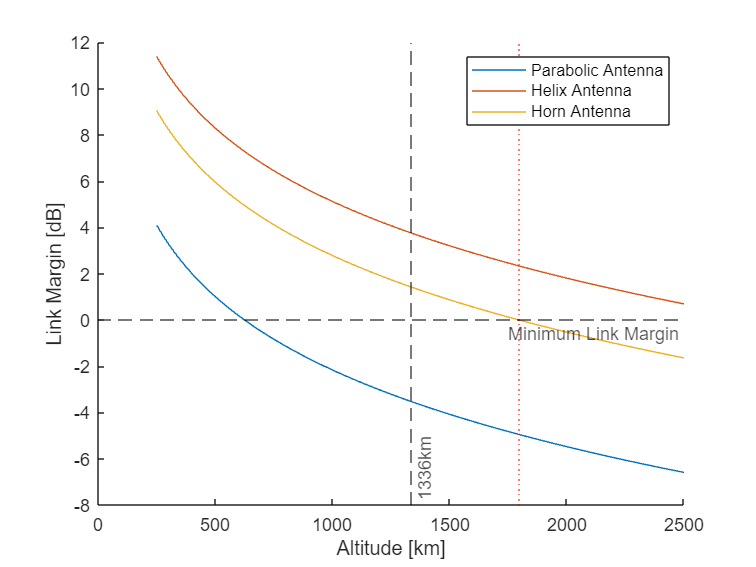

figure;
hold on;
plot(alt_range, link_margin);
xline(max_horn_altitude, 'r:');
ylabel('Link Margin [dB]');
xlabel('Altitude [km]');
xline(1336, 'k--', '1336km', 'LabelVerticalAlignment', 'bottom');
yline(0, 'k--', 'Minimum Link Margin', 'LabelVerticalAlignment', 'bottom');
legend('Parabolic Antenna', 'Helix Antenna', 'Horn Antenna');

## Discussion

- Given the chosen altitude of 1336km, only the horn antenna or the helix antenna would be suitable as the parabolic antenna has a negative link margin at 1336km altitude, meaning that it would not have enough gain to communicate with the ground station for this particular mission. 

- The parabolic antenna is not usable due to the negative link margin at the required altitude. The helix antenna, despite being above the link margin for all altitudes up to 2500km, would not be able to communicate with the receiving ground station because of its frequency range. Helix antennas operate between 300MHz and 3GHz, which is below the required downlink frequency of 8.9GHz. I would propose the horn antenna because it is the only antenna that can communicate with the ground station based on its frequency range (300MHz - 30GHz) and positive link margin at the required altitude. The horn antenna has the additional benefits of being 10kg lighter than the helix antenna as well as having 3 degrees extra of antenna beamwidth. On the other hand, it has lower transmission power, and higher noise temperature than the helix antenna, as well as having a limit to its altitude as it does not have sufficient link margin to communicate with the ground station beyond a certain altitude (roughly 1800km). 

- If I could adjust any part of either the space or ground segment by a factor of 2, I would double the ground station's antenna diameter to provide additional gain and therefore additional link margin to the mission. This would not increase the mass of the spacecraft itself, and might actually decrease the size of antenna required, thereby decreasing dry mass, increasing possible change in velocity given the same mass of fuel, which could then mean that less fuel is required for the same mission specification. This would save cost and complexity from the mission as well as perhaps allowing it to be a passenger on a rideshare mission, meaning that launch price would decrease considerably. On the other hand, it may delay the launch date as the ground station antenna needs to be upgraded so considerably, but the most likely outcome is that the mission would switch to a different antenna altogether, meaning that there would not be any effect on launch date. 